% tutorial for implementing NMFGOT
% NMFGOT is a novel algorithm for integrating analysis of microbiome and metabolomics data.
% import data

clear
addpath('external/')
load('data/data1.mat')

proData1 = filter_feas(X1,smps1,spe_names, 3, 0, 0); 
proData2 = filter_feas(X2,smps1,mtb_names, 2, 0, 0); 
X1 = proData1.data; X2 = proData2.data; 
X2 = log(X2+1);

num_clu = length(unique(label));
num_factor = num_clu;

% enhancing the initialization step of NMFGOT
[W1,H1] = nndsvd(X1',num_factor,0);
[W2,H2] = nndsvd(X2',num_factor,0);
Inits.H1 = H1; Inits.H2 = H2; 
Inits.W1 = W1; Inits.W2 = W2; 

Dist1 = dist2(X1,X1); S1 = affinityMatrix(Dist1,20); 
Dist2 = dist2(X2,X2); S2 = affinityMatrix(Dist2,20); 
S = SNF({S1,S2},20); Inits.S = S; 
clear S W1 H1 W2 H2 

% compute WMD distance between samples
addpath('emd/')
[WMD_D1, ~] = computing_WMD(X1');
[WMD_D2, ~] = computing_WMD(X2');

A1 = affinityMatrix(WMD_D1,20); A1 = A1./max(A1(:));
A2 = affinityMatrix(WMD_D2,20); A2 = A2./max(A2(:));

% implementing parameter selection
params = parameter_selection_mfop(X1', X2', A1, A2,num_factor);

% running NMFGOT algorithm
[S,W1,W2, H1,H2,obj] = mf_op(X1',X2',A1,A2,Inits,params);

iteration starts!
number of iteration:50  obj:109730.4828
number of iteration:100  obj:104259.3902
number of iteration:150  obj:102165.1288
number of iteration:200  obj:101070.5662
number of iteration:250  obj:100403.1274
number of iteration:300  obj:99956.2818
number of iteration:350  obj:99637.6747
number of iteration:400  obj:99399.9452
number of iteration:450  obj:99216.3621
number of iteration:500  obj:99070.7254
number of iteration:550  obj:98952.6614
number of iteration:600  obj:98855.2295
number of iteration:650  obj:98773.6157
number of iteration:700  obj:98704.3803
number of iteration:750  obj:98645.0022
number of iteration:800  obj:98593.5932
number of iteration:850  obj:98548.7121
number of iteration:900  obj:98509.2408
number of iteration:950  obj:98474.299
number of iteration:1000  obj:98443.1848
number of iteration:1050  obj:98415.3318
number of iteration:1100  obj:98390.2782
number of iteration:1150  obj:98367.644
number of iteration:1200  obj:98347.1137
number of itera

A = Wtrim(S,20); 

% clustering using Louvain algorithm
[clust,~,~] = getNCluster(A,num_clu,0,3,20); 
if length(unique(clust))== num_clu
    [ac,ari, nmi_value, ~] = CalcMetrics(label, clust); 
else
    [~, clust, ~] = SpectralClustering(A, num_clu); 
    [ac,ari, nmi_value, ~] = CalcMetrics(label, clust); 
end

ac: 0.8125	18/96	nmi:0.3745	
ari: 0.3836	


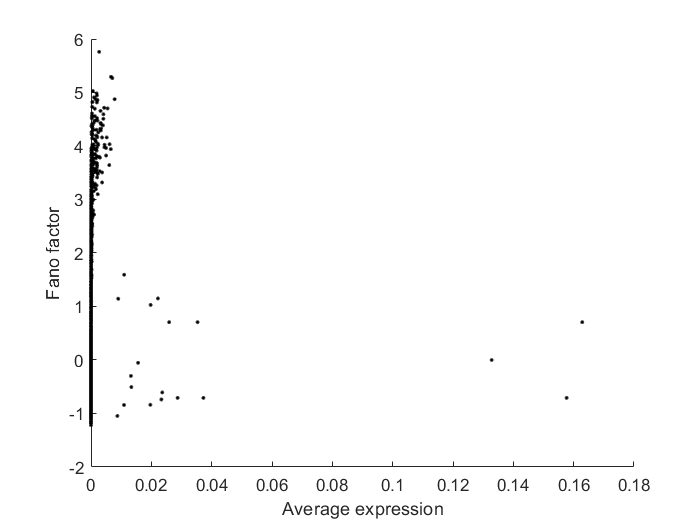

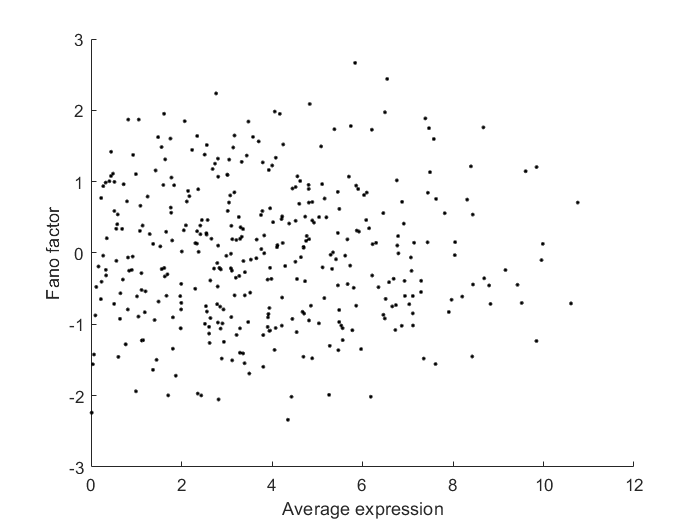

Parallelizing UMAP with MATLAB's 16 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v2.1.3
(ub=basic, us=supervised, ubt=template, ust=supervised template)


UMAP(method=MEX, n_neighbors=12, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.65, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.374820012392027, b=1.50487009200012, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]


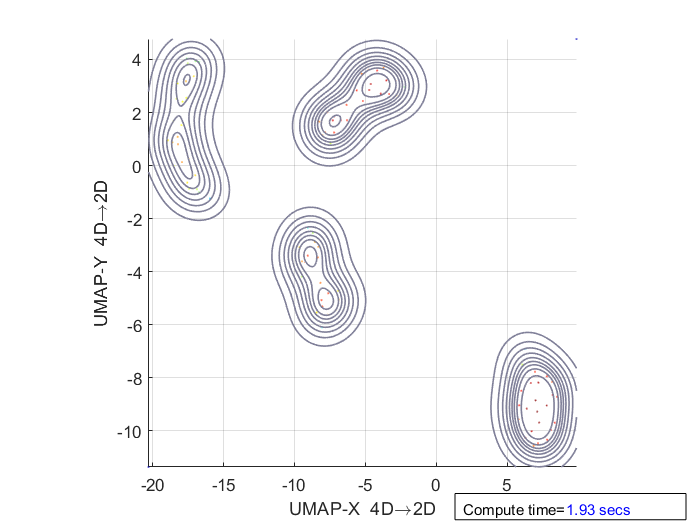

UMAP reduction finished (cost 1.94 secs)
 Finished basic (ub) reduction



% computing silhouette values
sil = silhouette_similarityMatrix(A,clust,num_clu);

% UMAP visualization on low-dimensional representation space
addpath('umapFileExchange/umap') 
addpath('umapFileExchange/util')
term = '.'; 
colors = generateColors(max(num_clu,length(unique(term))));

clust = label_name;
% D_orthnnmf = 1-S; D_orthnnmf = D_orthnnmf-diag(diag(D_orthnnmf));
% [reduction_snf, ~, ~, ~] = run_umap(D_orthnnmf,'metric','precomputed','min_dist',0.2,'n_neighbors',5); 
% NMFGOT on H
[reduction_snf, ~, ~, ~] = run_umap([H1;H2]','min_dist',0.65,'n_neighbors',12); 

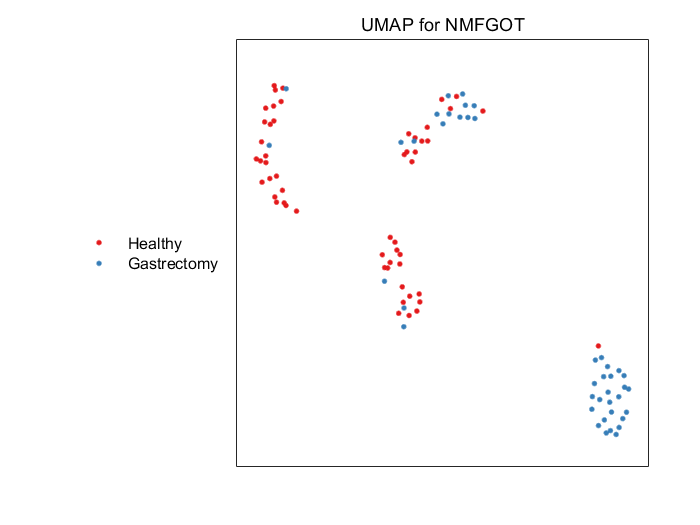


gscatter(reduction_snf(:,1),reduction_snf(:,2),clust,colors,[],10);
set(gca,'xtick',[],'ytick',[]);
title('UMAP for NMFGOT')
legend('Location','westoutside','Box','off','FontSize',9.5); 

legend('boxoff') 

在当前文件夹或 MATLAB 路径中未找到 'legendmarkeradjust'，但它位于:
 C:\Users\PC\Desktop\NMFGOT\host-gene microbe association\external
    E:\科研相关\research\JSNMF_BIB\jsnmf\parall multi-nm
    E:\科研相关\research\HONMF\HONMF\external

更改 MATLAB 当前文件夹 或 将其文件夹添加到 MATLAB 路径。